clear;
close all;
clc;
clf;
sympref('FloatingPointOutput',false);
sympref('AbbreviateOutput',true);
format LongEng;

% chart_frequency = [1993 2643 2993 3000 3500 3536 3610 3700 3750 3800 4000 5000 5063 6000 7000 8000 8282 9000 9409 10000 11000 12000 13000 14000 14500];   % selected frequencies in MHz
% filenames = cmd_sql_getfiles(sqlite_dbfile)

%chart_frequency = 3500:1:3900;   % selected frequencies in MHz
%filenames = ["L10_Dipole_v6.5ASYN_01VV_CFG-R.csv"; "20221231_L10_LowHeight_Dipole_v6.5_01_01VV_CFG-R.csv"; "20221231_L10_LowHeight_Dipole_v6.5_01_04HH_CFG-.csv"; "L10_Dipole_v6.5ASYN_04HH_CFG-.csv";"L10_dipole_v6.4_UFL_Meas_Rad_01VV_CFG-R_20221210.csv";"L10_dipole_v6.4_UFL_Meas_Rad_04HH_CFG-_20221210.csv"];
%chart_frequency = 2800:1:5000;   % selected frequencies in MHz
%chart_frequency = [3750];   % selected frequencies in MHz
%chart_frequency = 3500:1:3900;   % selected frequencies in MHz
%chart_frequency = [2984 2947 2990 3150 3496 3617 4000 5000 6000 7000 8000 9000 9500 10000];
%filenames = ["20221127_VMTM_Mono_L10_sub72x57_S2_01VV_CFG-R.csv"; "20221127_VMTM_Mono_L10_sub30x40_E03_01VV_CFG-R.csv";];
%savefile_types = ".png";
%savefile_types = [".png"; ".emf"; ".fig"; ".csv";];


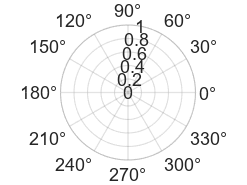

sqlite_dbfile = '..\output\antmeas.db';
dir_output = "..\output";
filenames = ["L10_Dipole_v6.5ASYN_04HH_CFG-.csv"; "L10_Dipole_v6.5ASYN_02VH_CFG-.csv";];
chart_frequency = 3000:1:4100;   % selected frequencies in MHz
savefile_types = [".png"; ".fig";];
alternate_filenames = ["E-plane E_theta"; "E-plane E_phi"];
cmdColorOrder = [1 0 1; 0 1 0; 0 0 1];          % https://jp.mathworks.com/help/matlab/creating_plots/defining-the-color-of-lines-for-plotting.html
cmdLineStyleOrder = ["-" "-" "-"];
cmdLineWidthOrder = [1; 1; 1];

cmd_genfig_polar_sql_comparison(sqlite_dbfile, dir_output, filenames, chart_frequency, savefile_types, alternate_filenames, cmdColorOrder, cmdLineStyleOrder, cmdLineWidthOrder);


filenames = ["20221127_VMTM_Mono_L10_sub72x57_S2_04HH_CFG-.csv"; "20221127_VMTM_Mono_L10_sub30x40_E03_04HH_CFG-.csv";];
cmd_genfig_polar_sql_comparison(sqlite_dbfile, dir_output, filenames, chart_frequency, savefile_types, alternate_filenames, cmdColorOrder, cmdLineStyleOrder, cmdLineWidthOrder);